clear all
close all
clc

s=tf('s');

[file_controllers, file_path] = uigetfile("controller_*.mat", "Controller");
load([file_path file_controllers])

[file_name, file_path] = uigetfile("*.mat", "Modello1");
load([file_path file_name])

[file_name, file_path] = uigetfile("*.mat", "Modello2");
load([file_path file_name])

F1_in=minreal(feedback(C1_in*modello_continuo_tf_j1,1))

F1_in =
 
  From input "u1" to output:
                                                                                      
     5.131e05 s^5 + 1.384e08 s^4 + 3.108e11 s^3 + 5.266e13 s^2 + 3.451e16 s + 3.785e17
                                                                                      
  ---------------------------------------------------------------------------------------
                                                                                         
  s^7 + 1893 s^6 + 2.35e06 s^5 + 1.335e09 s^4 + 8.327e11 s^3 + 1.664e14 s^2 + 4.133e16 s 
                                                                                         
                                                                             + 3.785e17  
                                                                                         
 
Continuous-time transfer function.



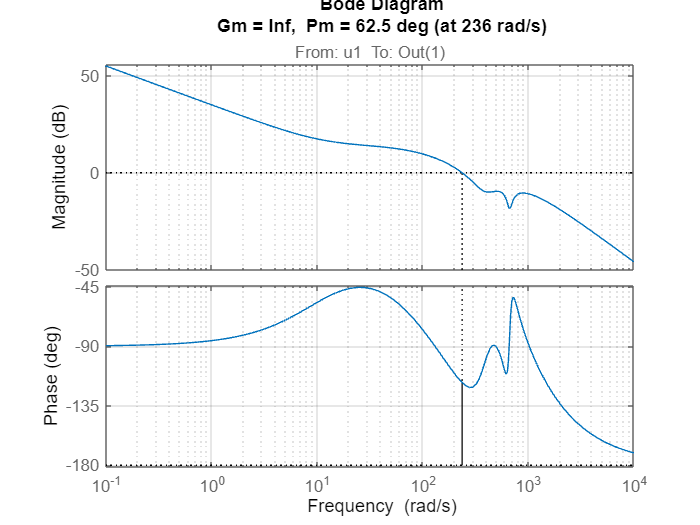

margin(C1_in*modello_continuo_tf_j1)
grid on


F2_in=minreal(feedback(C2_in*modello_continuo_tf_j2,1))

F2_in =
 
  From input "u1" to output:
                                                                                     
    6.019e05 s^5 + 1.353e08 s^4 + 8.517e11 s^3 + 9.678e13 s^2 + 2.247e17 s + 1.531e18
                                                                                     
  -------------------------------------------------------------------------------------
                                                                                       
  s^7 + 2961 s^6 + 5.011e06 s^5 + 4.387e09 s^4 + 3.526e12 s^3 + 9.107e14 s^2           
                                                                                       
                                                                + 2.809e17 s + 1.531e18
                                                                                       
 
Continuous-time transfer function.



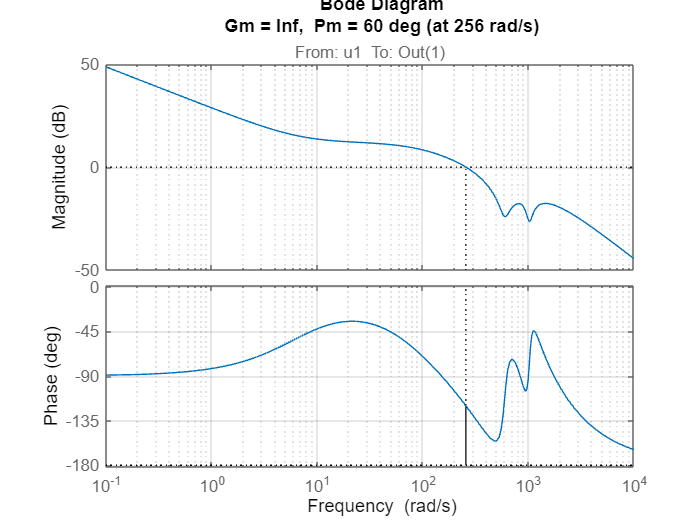

margin(C2_in*modello_continuo_tf_j2)
grid on

[Y1,T1]=step(F1_in);
t1_1=T1(min(find(Y1>=Y1(end)*0.0952)));
t1_2=T1(min(find(Y1>=Y1(end)*0.6321)));
syms t tau;
eqn1 = t1_1 == t+0.1*tau;
eqn2 = t1_2 == t + tau;
sol=solve([eqn1;eqn2]);
delay1_in=double(sol.t)

delay1_in = 3.1921e-04

if delay1_in < 0
    delay1_in = 0;
end
tau1_in=double(sol.tau)

tau1_in = 0.0052

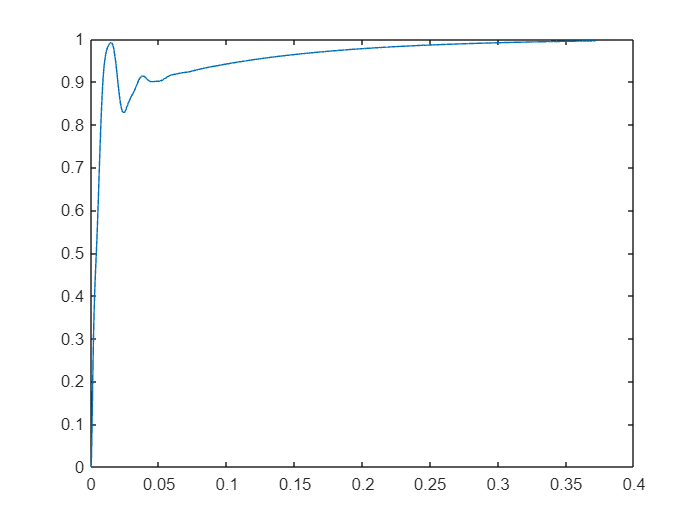

plot(T1,Y1)

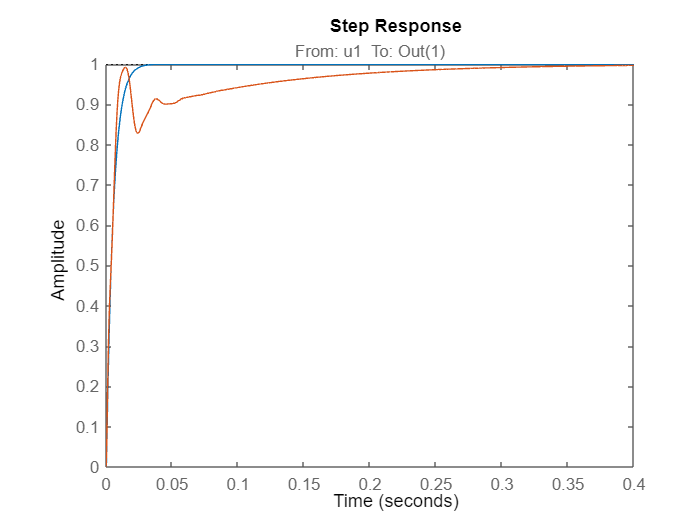

F1_in_approx = tf(1, [tau1_in 1]);
F1_in_approx.OutputDelay=delay1_in;
step(F1_in_approx,F1_in)




[Y2, T2]=step(F2_in);
t2_1=T2(min(find(Y2>=Y2(end)*0.0952)))

t2_1 = 8.5362e-04

t2_2=T2(min(find(Y2>=Y2(end)*0.6321)))

t2_2 = 0.0058

syms t tau
eqn1 = t2_1 == t+0.1*tau;
eqn2 = t2_2 == t + tau;
sol=solve([eqn1;eqn2])

sol = struct with fields:
      t: 3131416671926339/10376293541461622784
    tau: 57260190572367325/10376293541461622784


delay2_in=double(sol.t)

delay2_in = 3.0179e-04

if delay2_in < 0
    delay2_in = 0;
end
tau2_in=double(sol.tau)

tau2_in = 0.0055

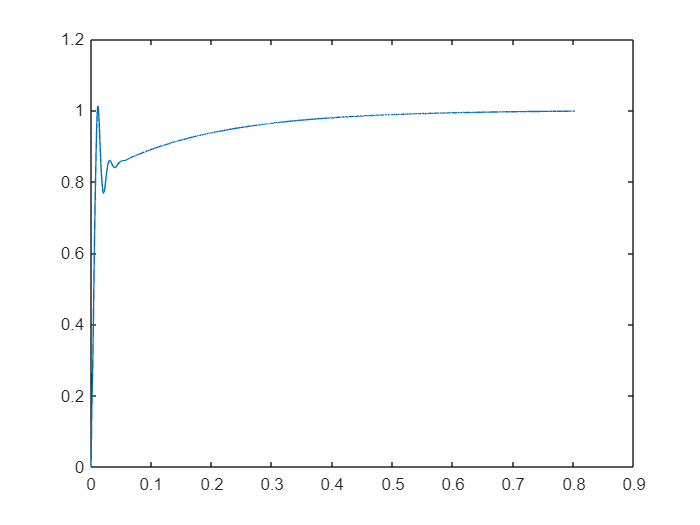

plot(T2,Y2)

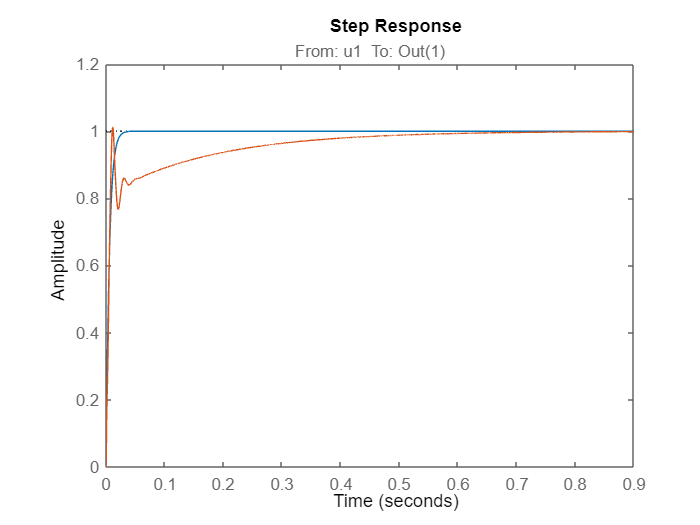

F2_in_approx = tf(1, [tau2_in 1]);
F2_in_approx.OutputDelay=delay2_in;
step(F2_in_approx,F2_in)

M1=tf(1,[tau1_in 1]);
M1.OutputDelay=delay1_in;

M2=tf(1,[tau2_in 1]);
M2.OutputDelay=delay2_in;


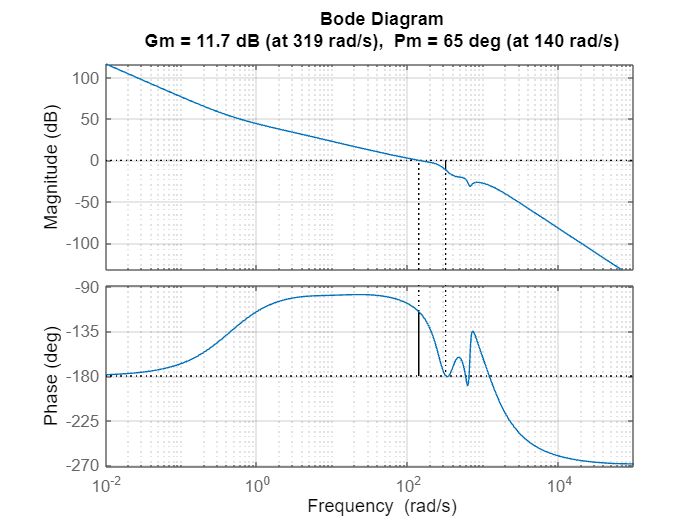


L1_out = C1_out*F1_in/s;
F1_out = feedback(L1_out,1);
margin(L1_out)
grid on

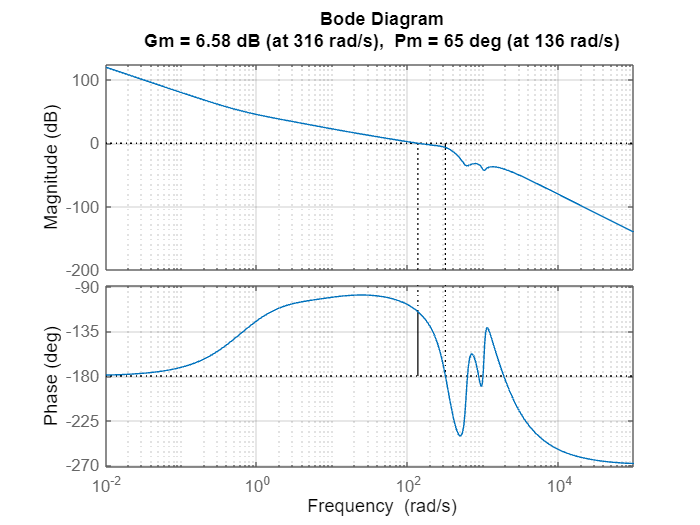


L2_out = minreal(C2_out*F2_in/s);
F2_out = feedback(L2_out,1);
margin(L2_out)
grid on

[Y1,T1]=step(F1_out);
t1_1=T1(min(find(Y1>=Y1(end)*0.0952)));
t1_2=T1(min(find(Y1>=Y1(end)*0.6321)));
syms t tau;
eqn1 = t1_1 == t+0.1*tau;
eqn2 = t1_2 == t + tau;
sol=solve([eqn1;eqn2]);
delay1_out=double(sol.t)

delay1_out = 0.0028

if delay1_out < 0
    delay1_out = 0;
end
tau1_out=double(sol.tau)

tau1_out = 0.0064

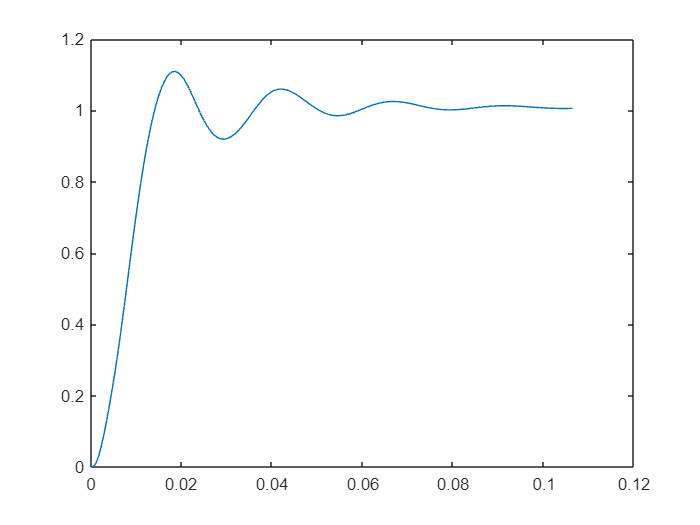

plot(T1,Y1)

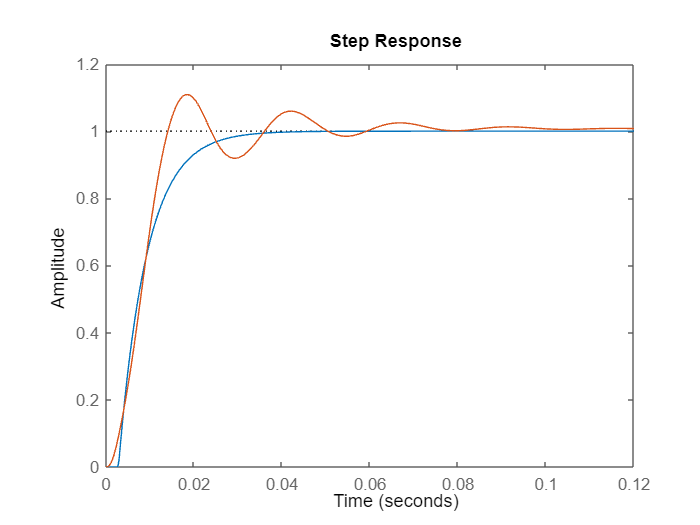

F1_in_approx = tf(1, [tau1_out 1]);
F1_in_approx.OutputDelay=delay1_out;
step(F1_in_approx,F1_out)




[Y2, T2]=step(F2_out);
t2_1=T2(min(find(Y2>=Y2(end)*0.0952)))

t2_1 = 0.0037

t2_2=T2(min(find(Y2>=Y2(end)*0.6321)))

t2_2 = 0.0095

syms t tau
eqn1 = t2_1 == t+0.1*tau;
eqn2 = t2_2 == t + tau;
sol=solve([eqn1;eqn2])

sol = struct with fields:
      t: 7936443180466147/2594073385365405696
    tau: 33577259609664475/5188146770730811392


delay2_out=double(sol.t)

delay2_out = 0.0031

if delay2_out < 0
    delay2_out = 0;
end
tau2_out=double(sol.tau)

tau2_out = 0.0065

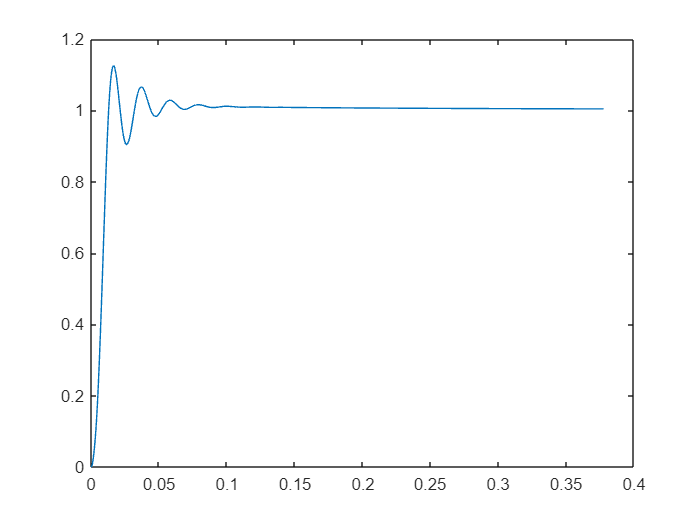

plot(T2,Y2)

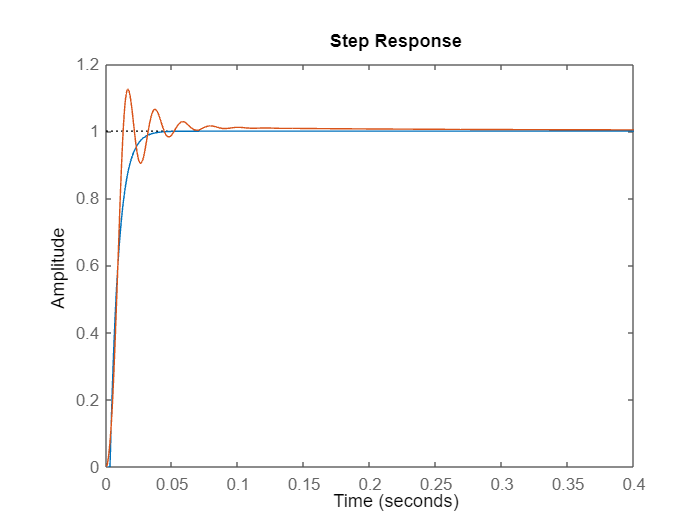

F2_in_approx = tf(1, [tau2_out 1]);
F2_in_approx.OutputDelay=delay2_out;
step(F2_in_approx,F2_out)

save(file_controllers+"_ff.mat","C1_out","C1_in","tau1_in", "tau1_out", "M1","C2_out","C2_in","tau2_in", "tau2_out", "M2");